% Save the updated FIS
%writefis(updated_fis, 'UpdatedFuzzyLogic.fis');
output

output = struct with fields:
      problemtype: 'boundconstraints'
         rngstate: [1×1 struct]
      generations: 15
        funccount: 758
          message: 'ga stopped because it exceeded options.MaxGenerations.'
    maxconstraint: 0
       hybridflag: []


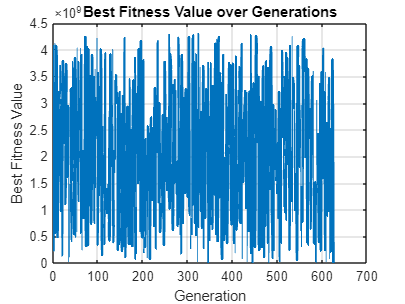


% Plot the best fitness value over generations
figure;
plot(output.rngstate.State, 'LineWidth', 2);
title('Best Fitness Value over Generations');
xlabel('Generation');
ylabel('Best Fitness Value');
grid on;

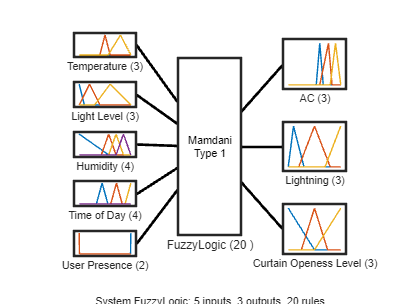

%optimized FIS
plotfis(updated_fis);

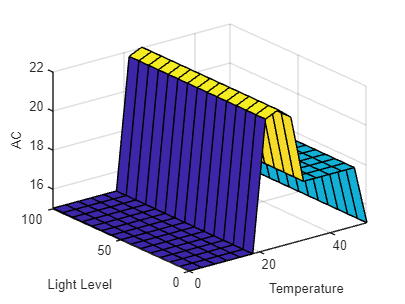

gensurf(updated_fis);

% Extract original parameters
original_params = [];
for i = 1:numel(fis.Inputs(1).MembershipFunctions)
    original_params = [original_params fis.Inputs(1).MembershipFunctions(i).Parameters];
end
original_params

original_params =      0    11    22    20    25    30    28    40    50


opt_params

opt_params =     0.2330    0.9000    0.1000    0.6691    0.1000


% Plot original parameters vs optimized parameters
figure;
bar([original_params; opt_params]');

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

title('Comparison of Original and Optimized Parameters');
xlabel('Membership Function');
ylabel('Parameter Value');
legend('Original', 'Optimized');